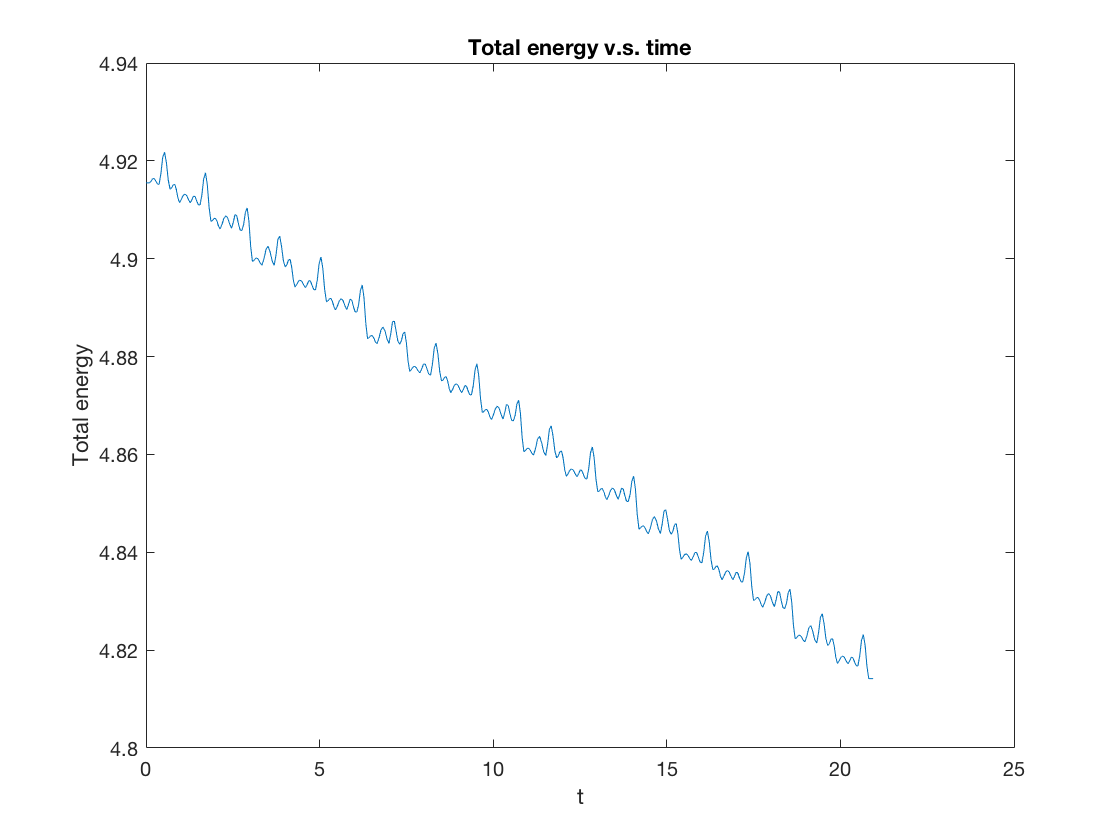

close all

[T,sol] = pendulum2(3,1,0);

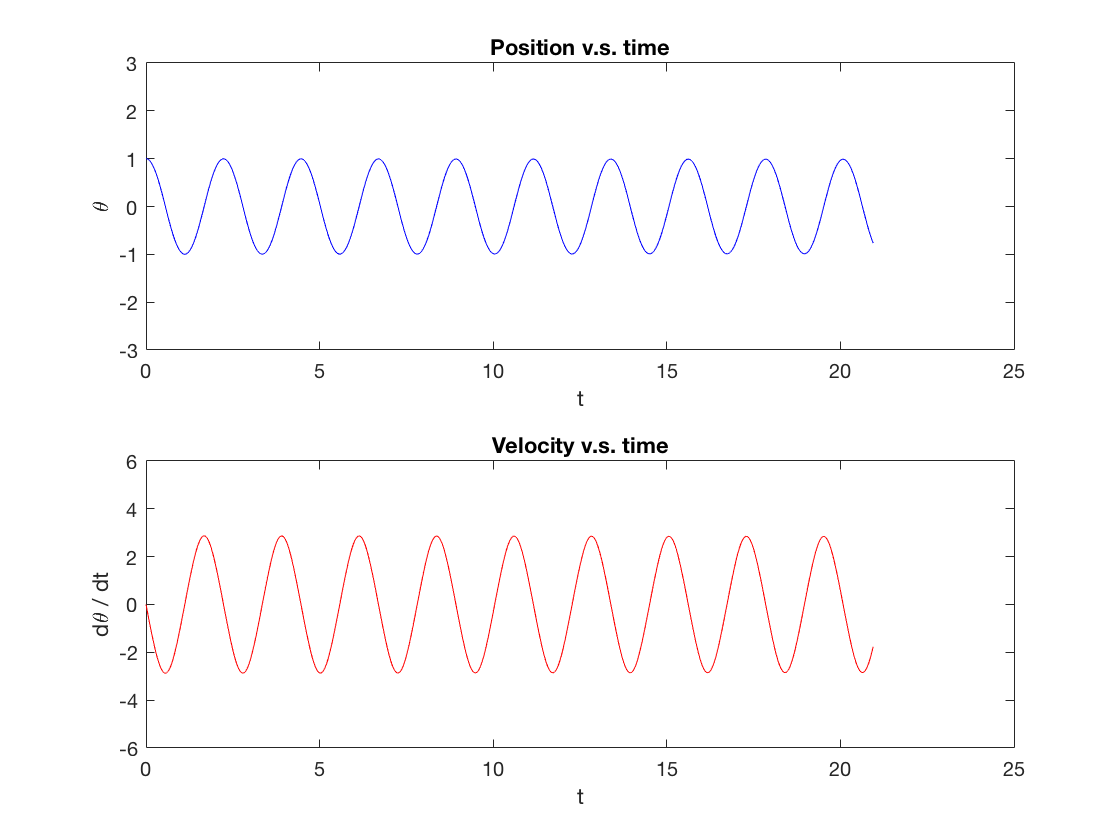

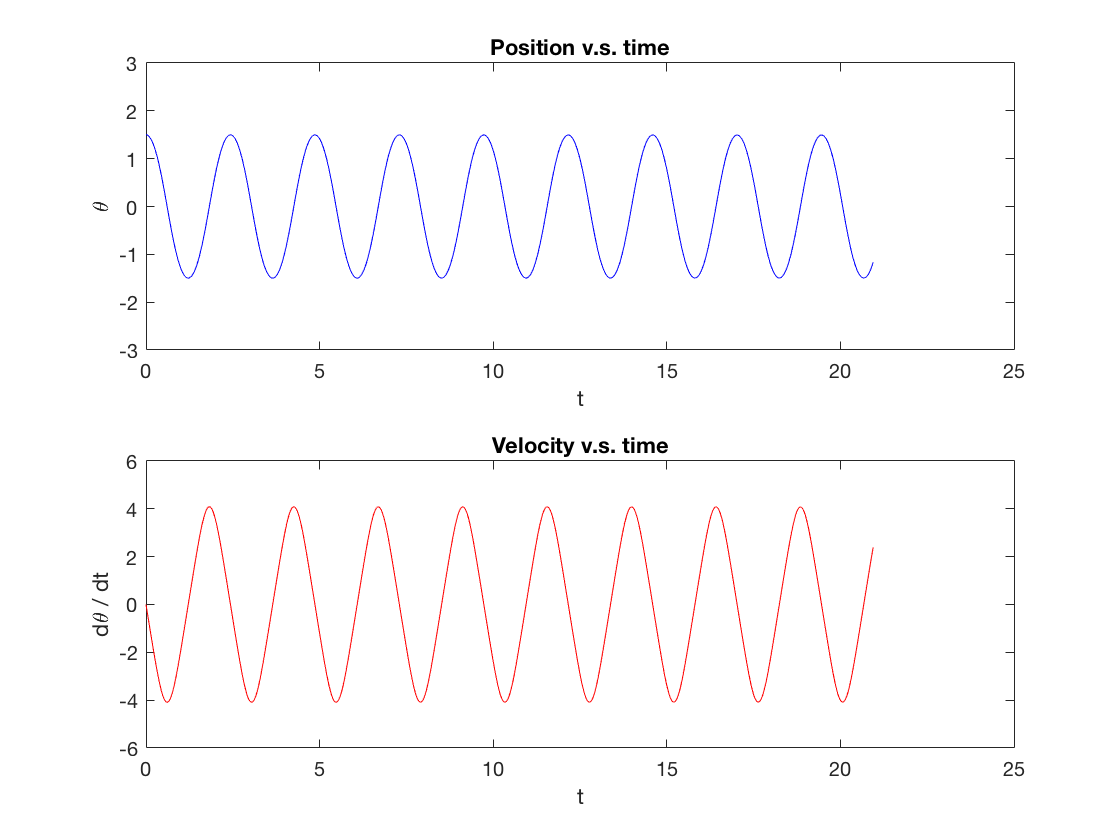

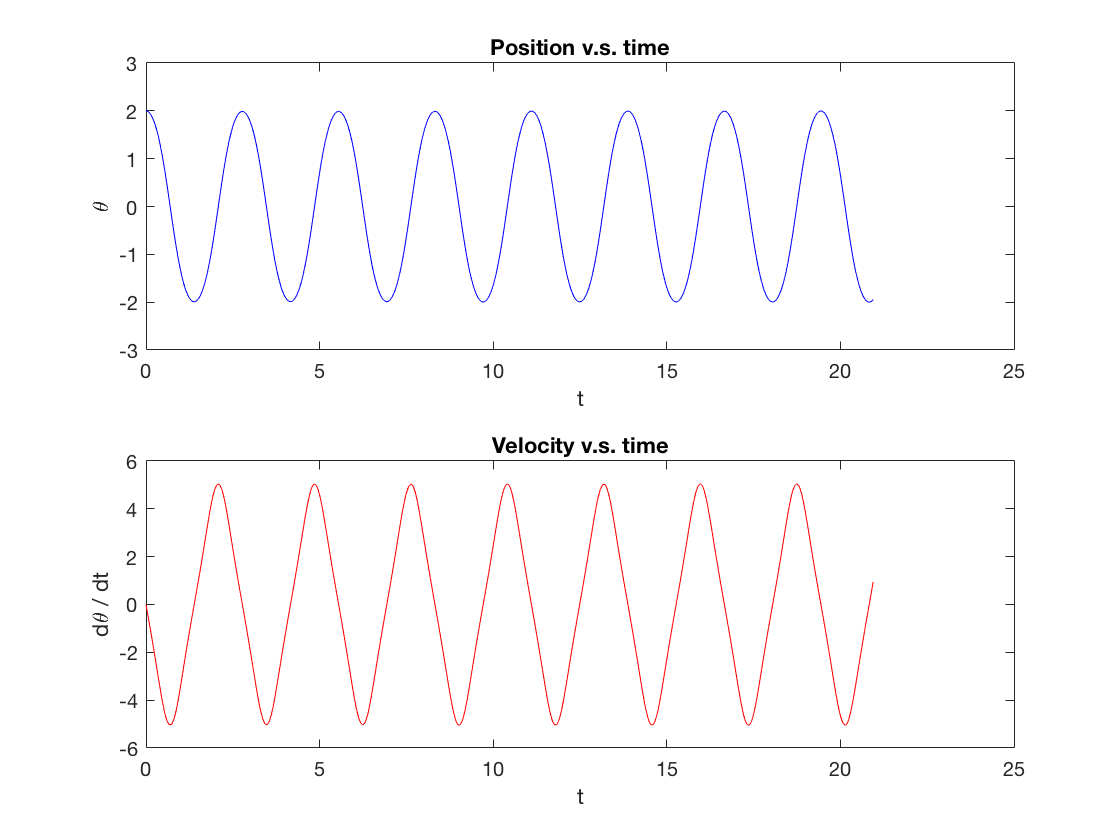

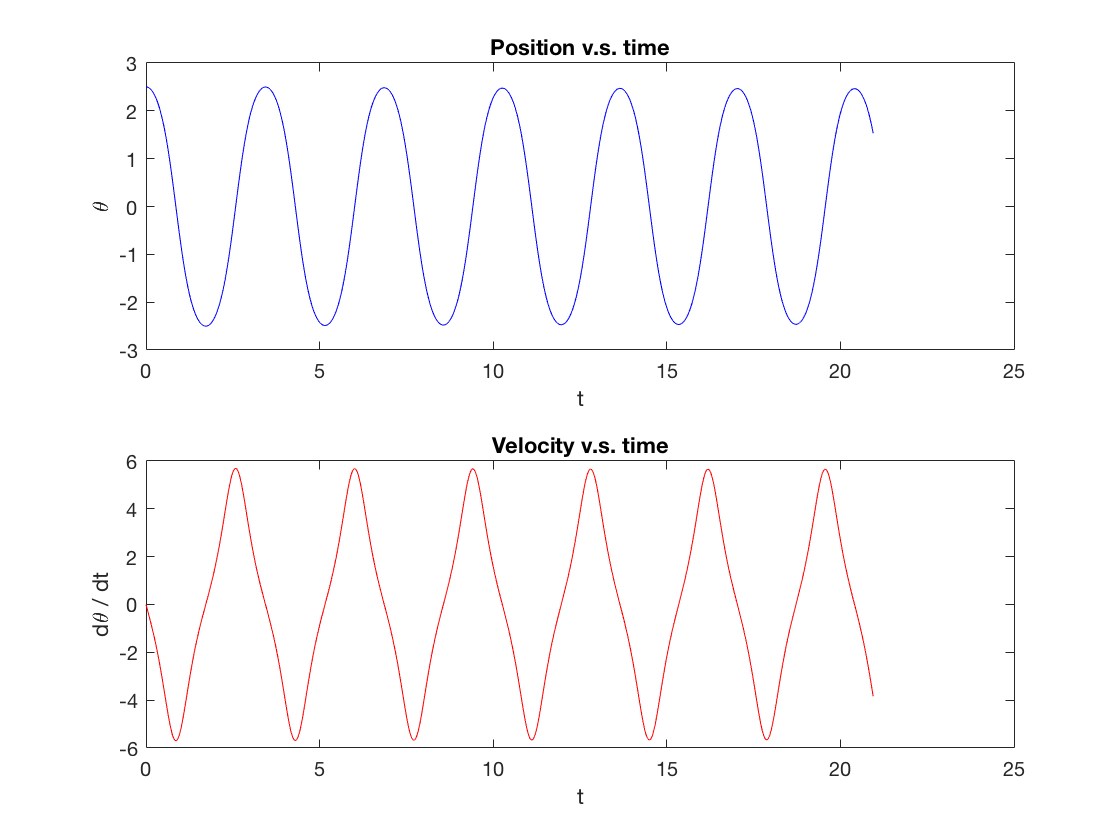

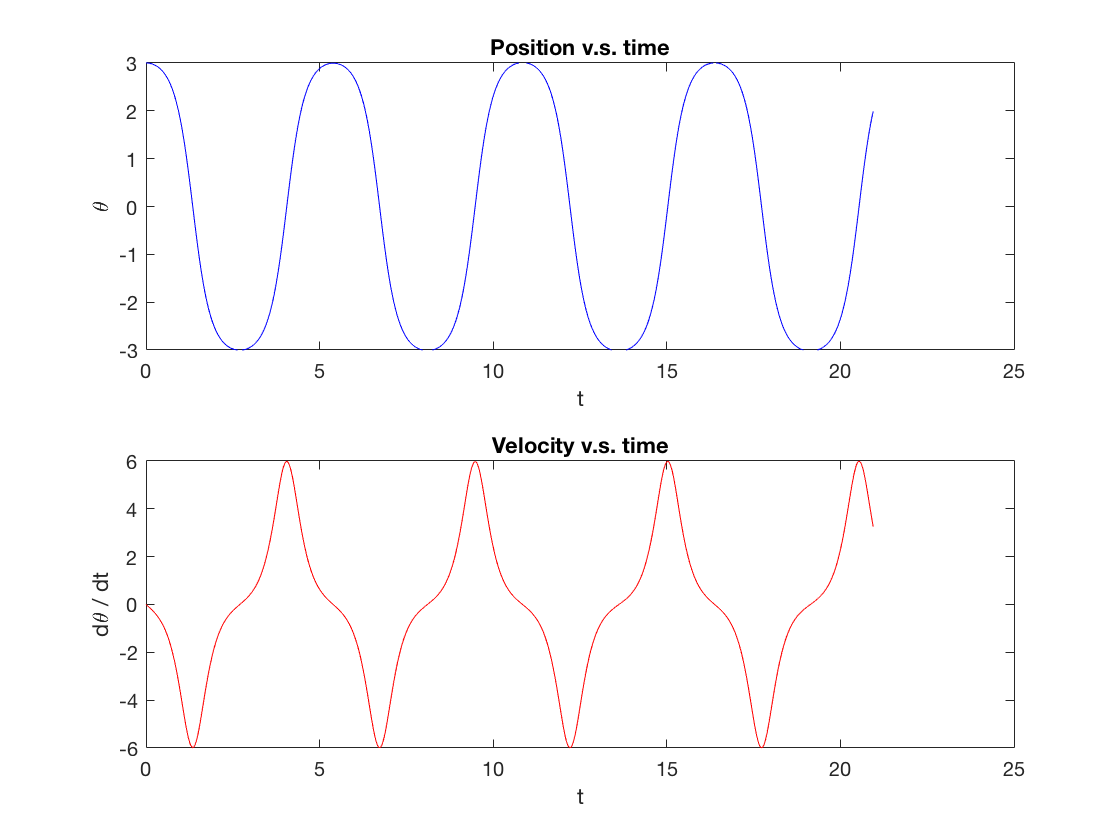


theta0 = [1, 1.5, 2.0, 2.5, 3.0];
% theta0 = [0.1, 0.2, 0.4, 0.8, 1];
T_list = [];
thetaMax = [];

for i=1:5
    
    [T,sol] = pendulum2(3,theta0(i),0,0);
    T_list(i) = T;
    thetaMax(i) = max(sol(:,2));
    
    figure
    subplot(2,1,1)
    plot(sol(:,1),sol(:,2),'b')
    title('Position v.s. time')
    ylim([-3 3])
    xlabel('t')
    ylabel('\theta')
    subplot(2,1,2)
    plot(sol(:,1),sol(:,3),'r')
    title('Velocity v.s. time')
    ylim([-6 6])
    xlabel('t')
    ylabel('d\theta / dt')

end

There seems a large total energy drift in my calculation. But it looks fine with the following plot. I think there is something wrong in my calculation for total energy, but have no idea why.

We set initial conditions to be d(theta)/dt = 0, theta = 1, 1,5, 2, 2.5, 3 instead of the set described in problems set. 

We can see that with larger initial angle, the period of the oscillation becomes bigger(also shown in the following graph). And the range of angular frequency becomes larger, which means pendulum has **larger velocity when passing the equilibrium point**, and stays longer in the large angle region. This also indicates larger period.

Now we plot T and theta_max.

Note that period in linear case is just 2 * pi / omega.

figure
plot(thetaMax,T_list,'b.--','MarkerSize',20)
yline(2*pi/3,'-.r')

ans =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 2.0944
            Color: [1 0 0]
        LineStyle: '-.'
        LineWidth: 0.5000
            Label: ''
      DisplayName: ''

  Show all properties


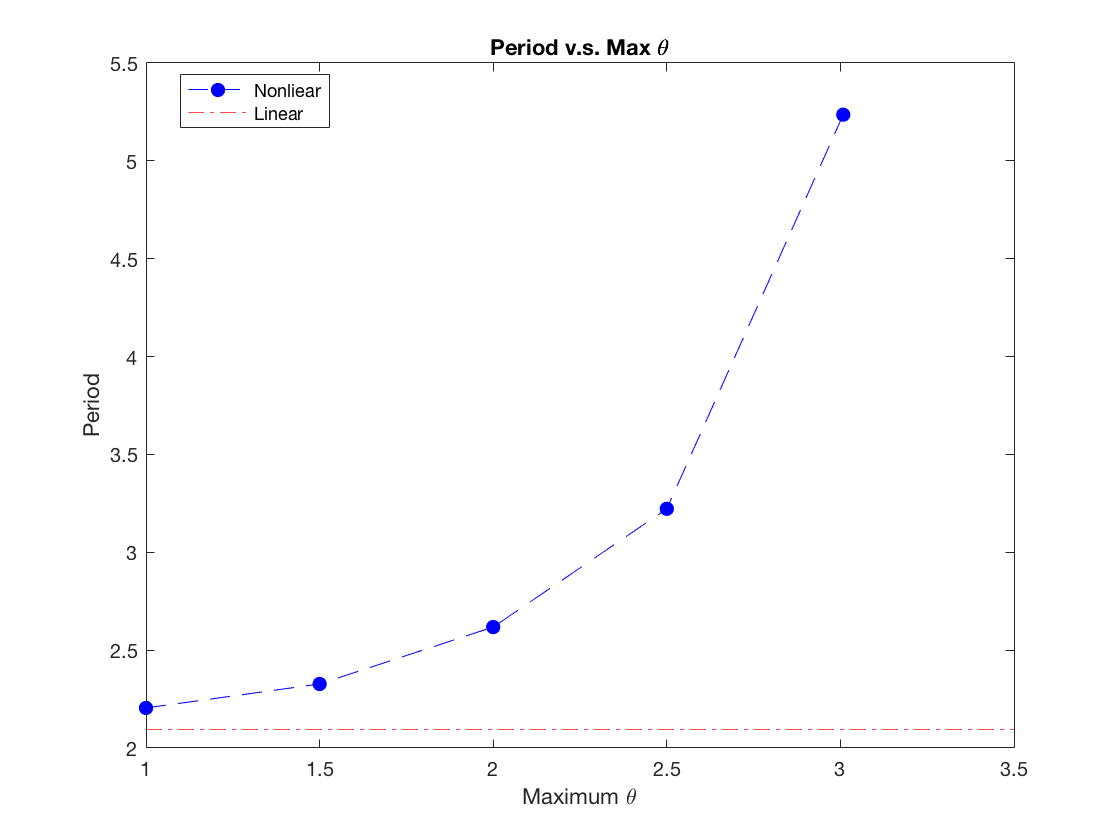

legend('Nonliear','Linear','Location','best')
title('Period v.s. Max \theta')
xlabel('Maximum \theta')
ylabel('Period')

As shown, **period in nonlinear case is larger than in linear case**. And with larger initial angle, the period is larger.